## Part 1:

### 1.

rng(1);
b_tx = bit_gen(10, 2)

b_tx = 10×2 int32 matrix
   0   0
   1   1
   0   0
   0   1
   0   0
   0   1
   0   0
   0   1
   0   0
   1   0


### 2.

b_gray = gray_code(2)

b_gray =      0     0
     0     1
     1     1
     1     0



sym_idx = zeros(10, 1);
b_tx_dec = bi2de(b_tx, 'left-msb');
b_gray_dec = bi2de(b_gray, 'left-msb');
for c = 1:10
    sym_idx(c, 1) = find(b_gray_dec == b_tx_dec(c));
end
sym_idx

sym_idx =      1
     3
     1
     2
     1
     2
     1
     2
     1
     4



modulation = 'pam';
M = 4;
[cons, ~] = constellation(M, modulation);
mod_sym = zeros(10, 1);
for c = 1:10
    mod_sym(c, 1) = cons(sym_idx(c, 1));
end
mod_sym

mod_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


### 3.

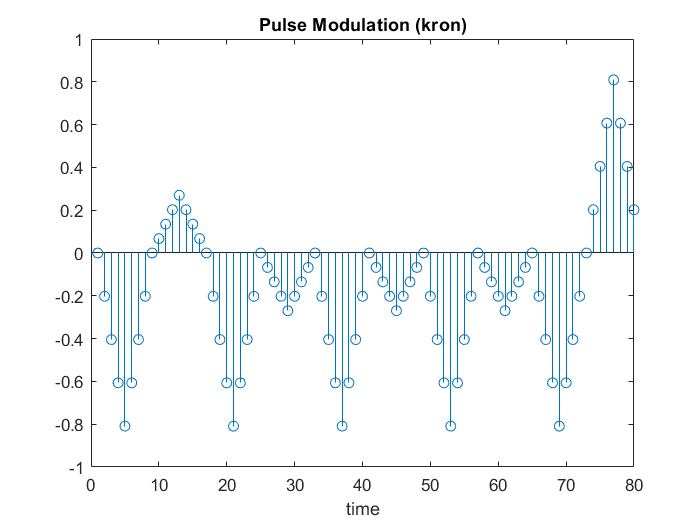

pulse_name = 'triangular';
pulse_shape_mode = 'kron';
fs = 1;
smpl_per_symbl = 8;
[tx_smpl1, cons1] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_shape_mode);
stem(tx_smpl1)
xlabel('time')
title('Pulse Modulation (kron)')

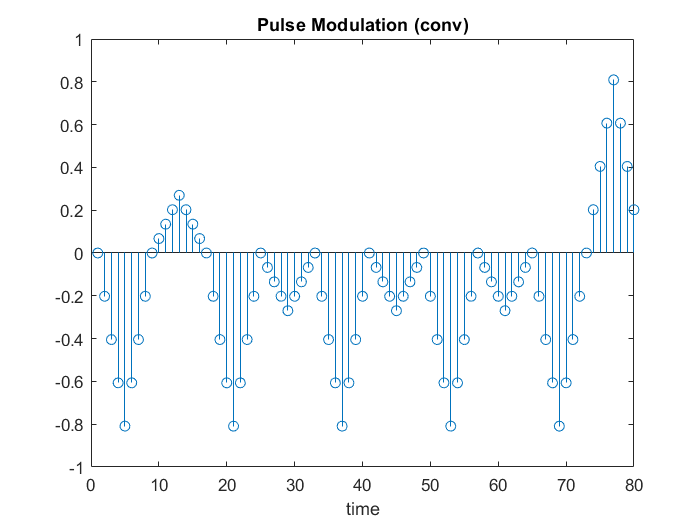


pulse_shape_mode = 'conv';
[tx_smpl2, cons2] = pulse_modulation(sym_idx, modulation, M, fs, 8, 'triangular', pulse_shape_mode);
stem(tx_smpl2)
xlabel('time')
title('Pulse Modulation (conv)')

#### As generated pulses have no interference, pulse modulation plots have the same output.

## Part 2:

### 1.

[p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl);
rx_mode = 'correlator';
[rx_sym1] = corr_match(tx_smpl1, p, smpl_per_symbl, rx_mode)

rx_sym1 =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


rx_mode = 'matched_filter';
[rx_sym2] = corr_match(tx_smpl1, p, smpl_per_symbl, rx_mode)

rx_sym2 =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


### 2.

[det_sym] = min_dist_detector(rx_sym1, cons)

det_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


### 3.

[det_sym_idx, rx_sym] = pulse_demodulation(tx_smpl1, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode)

det_sym_idx =      1
     3
     1
     2
     1
     2
     1
     2
     1
     4


rx_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


### 4.

det_bit = b_gray(det_sym_idx, :)

det_bit =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0


det_bit_dec = bi2de(det_bit, 'left-msb')

det_bit_dec =      0
     3
     0
     1
     0
     1
     0
     1
     0
     2


#### As the outputs show, demodulated bits are the same as the generated ones that transfered.

## Functions Definition:

### part 1.

#### 1.

function [b] = bit_gen(N, k)
b = int32(randi([0, 1], [N, k]));
end

#### 2.

#### gray code

function [b_gray] = gray_code(k)
b_gray = ones(2^k, k);
b_gray(1:2^(k-1), 1) = 0;
if k ~= 1
    tmp = gray_code(k-1);
    b_gray(1:2^(k-1), 2:k) = tmp;
    b_gray(2^(k-1) + 1:2^k, 2:k) = flip(tmp, 1);
end
end

#### constellation

function [cons, Es_avg] = constellation(M, modulation)
if strcmp(modulation, 'pam')
    Es_avg = (M^2 - 1)/3;
    cons = (-M+1:2:M-1).'/ sqrt(Es_avg);
elseif strcmp(modulation, 'psk')
    m = (1:M).';
    cons = cos(2*pi*(m-1)/M) + 1j * sin(2*pi*(m-1)/M);
elseif strcmp(modulation, 'qam')
    m1 = fix(log2(M) / 2);
    m2 = log2(M) - m1;
    v1 = 1j * (-2^m1+1:2:2^m1-1).';
    v2 = (-2^m2+1:2:2^m2-1);
    cons = ones(M, 1);
    for k = 1:2^m2
        if mod(k, 2) == 0
            cons(2^m1 * (k-1) + 1:2^m1 * k, 1) = v1 + v2(k) * ones(2^m1, 1);
        else
            cons(2^m1 * (k-1) + 1:2^m1 * k, 1) = flip(v1) + v2(k) * ones(2^m1, 1);
        end
    end
    Es_avg = sum(abs(cons).^2) / M;
    cons = cons / sqrt(Es_avg);
end
Es_avg = 1;
end

#### 3.

#### pulse shape

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin)
Ts = smpl_per_symbl * fs;
t = (0:smpl_per_symbl-1)/fs;
if strcmp(pulse_name, 'rectangular')
    p = ones(smpl_per_symbl, 1);
elseif strcmp(pulse_name, 'triangular')
    p = (max(Ts/2 - abs(t-Ts/2), 0)).';
elseif strcmp(pulse_name, 'sine')
    p = sin(pi*t.'/Ts);
end
p = p / sqrt(sum(p.^2));
end

#### upsample

function [y] = upsmpl(x, N)
y = zeros(1, (length(x) - 1)*(N - 1) + length(x));
for i = 1:N:(length(x) - 1)*(N - 1) + length(x)
    y(i) = x((i - 1)/N + 1);
end
end

#### pulse modulation

function [tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name , pulse_shape_mode, varargin)
[cons, ~] = constellation(M, modulation);
mod_sym = zeros(10, 1);
for c = 1:10
    mod_sym(c, 1) = cons(sym_idx(c, 1));
end
[p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl); 
if strcmp(pulse_shape_mode, 'kron')
    [p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl);
    tx_smpl = kron(mod_sym, p);
elseif strcmp(pulse_shape_mode, 'conv')
    s = upsmpl(mod_sym, length(p));
    tx_smpl = conv(s, p);
end
end

### part 2.

#### 1.

function [rx_sym] = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode)
rx_sym = zeros(length(rx_smpl)/smpl_per_symbl, 1);
if strcmp(rx_mode, 'correlator')
    for c = 1:smpl_per_symbl:length(rx_smpl)
        rx_sym((c-1)/smpl_per_symbl + 1, 1) = sum(rx_smpl(c:c+smpl_per_symbl-1, 1) .* conj(p));
    end
elseif strcmp(rx_mode, 'matched_filter')
    tmp = conv(rx_smpl, flip(conj(p)), 'valid');
    rx_sym = tmp(1:smpl_per_symbl:end);
end
end

#### 2.

function [det_sym] = min_dist_detector(rx_sym, constellation)
[~, det_sym_idx] = min(abs(rx_sym - constellation.'), [], 2);
det_sym = constellation(det_sym_idx);
end

#### 3.

function [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, varargin)
[p, ~] = pulse_shape(pulse_name, fs, smpl_per_symbl);
rx_sym = zeros(length(rx_smpl)/smpl_per_symbl, 1);

if strcmp(rx_mode, 'correlator')
    for c = 1:smpl_per_symbl:length(rx_smpl)
        rx_sym((c-1)/smpl_per_symbl + 1, 1) = sum(rx_smpl(c:c+smpl_per_symbl-1, 1) .* conj(p));
    end
elseif strcmp(rx_mode, 'matched_filter')
    tmp = conv(rx_smpl, flip(conj(p)), 'valid');
    rx_sym = tmp(1:smpl_per_symbl:end);
end

[cons, ~] = constellation(M, modulation);
[~, det_sym_idx] = min(abs(rx_sym - cons.'), [], 2);
end